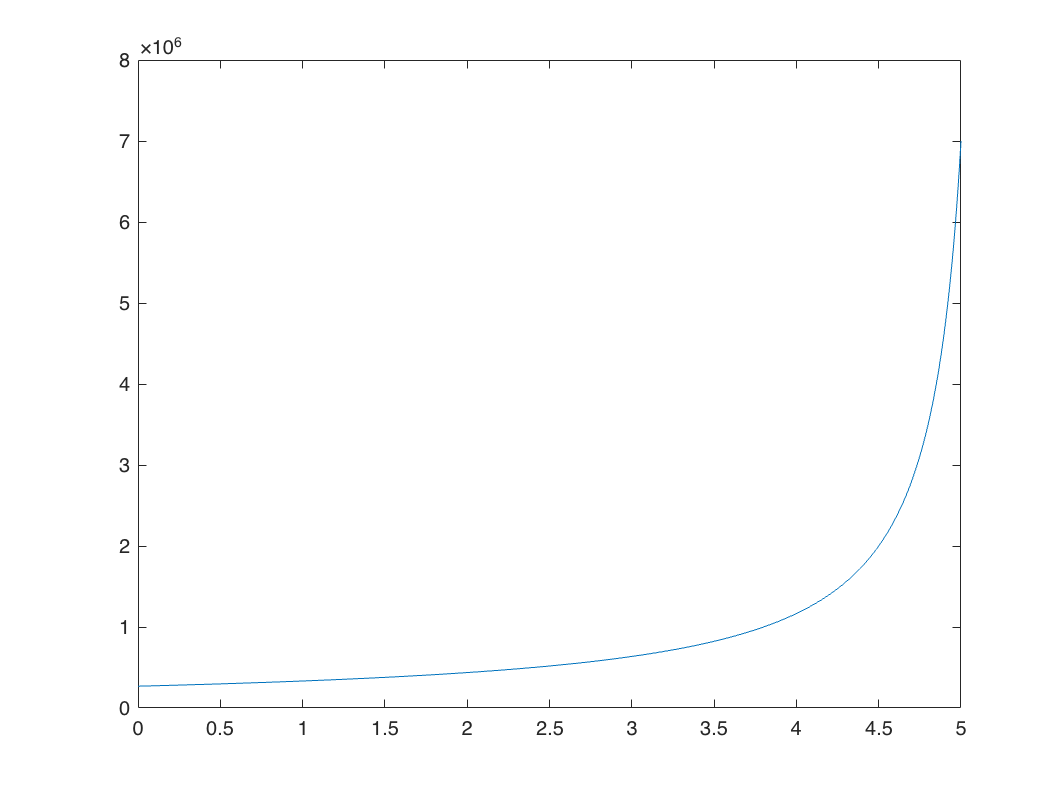

%RO = 2.5;%R0 value
%can change this value in the function
N = 10000;
TR = 14;
fT = 2./7;
s = 0.9;
SS = 0.6;
Reff =@(x) x./(1+SS+s.*fT.*TR);
%Reff =RO./(1+SS+s.*fT.*TR);
%RO = @(y) y;
%A =  @(x) (-N.*TR.*10.*Reff.*x)./(RO.*Reff - RO) + exp((RO./TR).*(1-(1./Reff)).*x);
%days = 0:0.1:100;
%plot(days, A(days))
x1 = 0:0.0001:5;
%plot(x1, Reff(x1))

A =  @(x) (-N.*TR.*10.*Reff(x))./(x.*Reff(x) - x) + exp((x./TR).*(1-(1./Reff(x))));

plot(x1, A(x1))